clear all
prob=optimproblem; %initializzi il problema

StateUpdate=@(x1,x2)[x1,x2]; %Definisci la funzione di state update, così se dobbiamo passare 
                             %cose costanti come gli speed profiles non dobbiamo
                             %passarli ogni volta. Questa è a caso per
                             %testare
N=10; %Time horizon

SOC_lowerbound=0.20; %Bounds del SOC
SOC_higherbound=0.80;

%Definisci le variabili di ottimizzazione, SOC e mf devono essere
%considerate come tali perché mf ci serve per la funzione di costo mentre
%il SOC è la variabile di stato, ci serve in tutti i punti. Ce ne sono
%altre?
u=optimvar('u',N,"LowerBound",-1,"UpperBound",1);
SOC=optimvar('SOC',N,"LowerBound",SOC_lowerbound,"UpperBound",SOC_higherbound);
mf=optimvar('mf',N);

%Definisci gli equality constraint, se aggiungiamo variabili su cui mettere constraints
% va cambiato il numero N_eq_constraints
N_eq_constraints=2;
eq_constraints=optimconstr(N,N_eq_constraints);

%Lo stato iniziale va fissato
eq_constraints(1,:)= [mf(1),SOC(1)]==[0,0.55];

for i=2:N
    eq_constraints(i,:)= [mf(i),SOC(i)]==StateUpdate(u(i-1),SOC(i-1));
end

prob.Constraints.equality=eq_constraints;

%Definisci gli inqeuality constraint su u, non so se ce ne siano altri
%dinamici, come funziona?
N_in_constr=1;

ineq_constraintsL=optimconstr(N);
ineq_constraintsH=optimconstr(N);
for i=1:N
    ineq_constraintsL(i)= u(i)<= 1;%DA CAPIRE
    ineq_constraintsH(i)= u(i)>=-1; %DA CAPIRE
end

 prob.Constraints.inequalityL=ineq_constraintsL;
 prob.Constraints.inequalityH=ineq_constraintsH;

%Definisci la cost function e gli stati iniziali
prob.Objective=sum(mf); %+sum(SOC-SOC(0))?
initialGuess.u=zeros(N,1);

%Simuli tutto con u=0, ora non ho la funzione, quando la avremo non
%servirà più l'inizializzazione punto per punto
initial_SOC=0.55*ones(1,N);
initial_mf=ones(1,N);
%[initial_Tel,initial_Tice,initial_etaice,initial_etael,Minitial_SOC]=

initialGuess.SOC=initial_SOC;
initialGuess.mf=initial_mf;

show(prob)


  OptimizationProblem : 

	Solve for:
       SOC, mf, u

	minimize :
       mf(1) + mf(2) + mf(3) + mf(4) + mf(5) + mf(6) + mf(7) + mf(8) + mf(9) + mf(10)


	subject to equality:
       mf(1) == 0
       mf(2) - u(1) == 0
       mf(3) - u(2) == 0
       mf(4) - u(3) == 0
       mf(5) - u(4) == 0
       mf(6) - u(5) == 0
       mf(7) - u(6) == 0
       mf(8) - u(7) == 0
       mf(9) - u(8) == 0
       mf(10) - u(9) == 0
       SOC(1) == 0.55
       -SOC(1) + SOC(2) == 0
       -SOC(2) + SOC(3) == 0
       -SOC(3) + SOC(4) == 0
       -SOC(4) + SOC(5) == 0
       -SOC(5) + SOC(6) == 0
       -SOC(6) + SOC(7) == 0
       -SOC(7) + SOC(8) == 0
       -SOC(8) + SOC(9) == 0
       -SOC(9) + SOC(10) == 0

	subject to inequalityL:
       u(1) <= 1
       u(2) <= 1
       u(3) <= 1
       u(4) <= 1
       u(5) <= 1
       u(6) <= 1
       u(7) <= 1


sol=solve(prob,initialGuess)

Solving problem using linprog.

Optimal solution found.



sol = struct with fields:
    SOC: [10×1 double]
     mf: [10×1 double]
      u: [10×1 double]


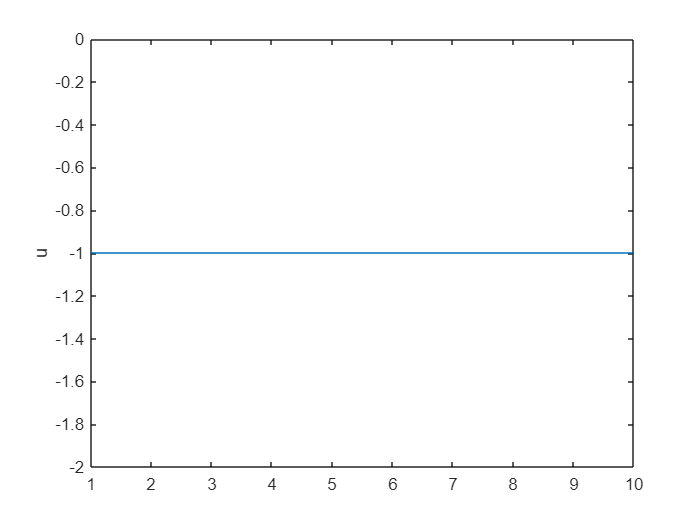

plot(sol.u)
ylabel('u')

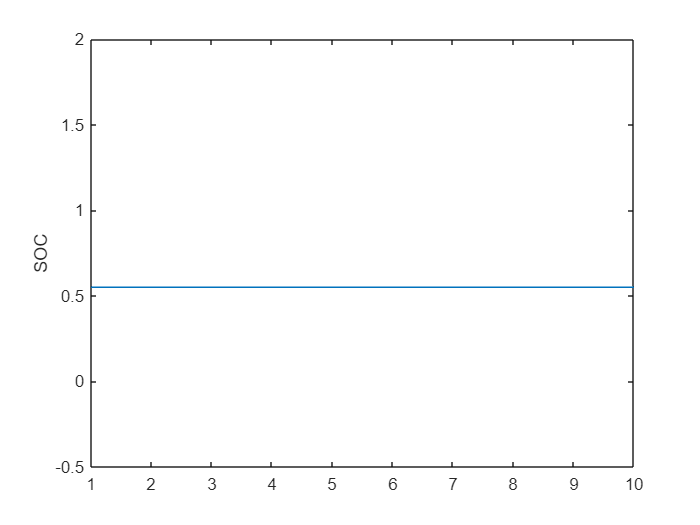

plot(sol.SOC)
ylabel('SOC')

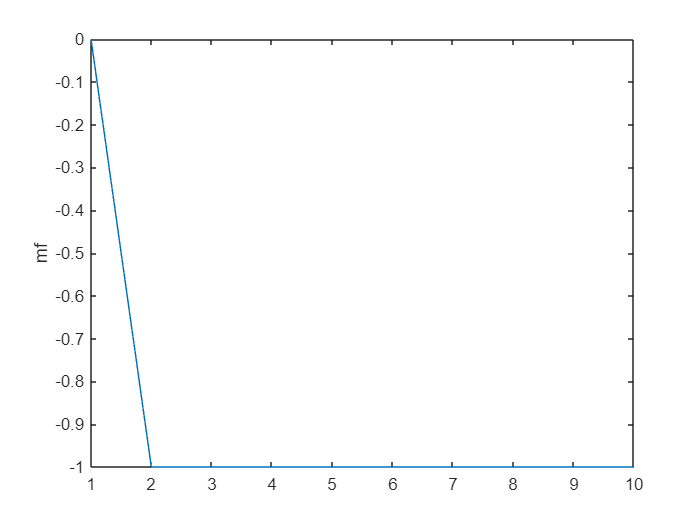

plot(sol.mf)
ylabel('mf')